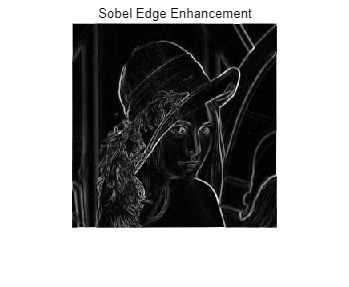

img = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\Image\lena.bmp');
img_gray = im2gray(img);
% 使用Sobel算子
result_sobel = sobel_edge_enhancement(img_gray);
figure, imshow(result_sobel, []), title('Sobel Edge Enhancement');

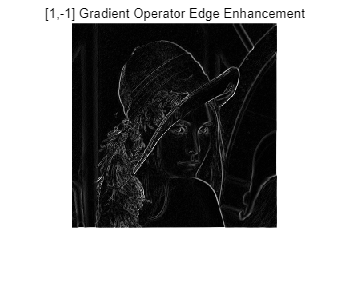


% 使用[1,-1]梯度算子
result_custom = custom_edge_enhancement(img_gray);
figure, imshow(result_custom, []), title('[1,-1] Gradient Operator Edge Enhancement');

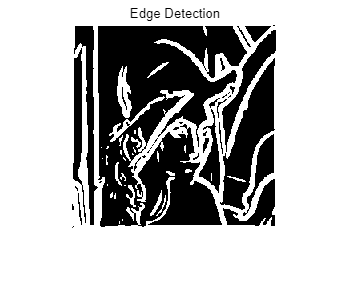


%使用你已经编写的高斯和边缘增强方法来进行边缘检测。实验使用不同程度的平滑（即，多次应用高斯滤波器）和不同的阈值。
% 你能描述改变这些参数是如何影响结果的吗？
%如何影响结果的描述：
%高斯平滑：增加高斯滤波器的应用次数会使图像更加平滑，但也可能导致边缘模糊。因此，过多的平滑可能会丢失一些重要的边缘信息。
%阈值：较低的阈值可能会检测到更多的边缘，但也可能包括一些噪声。较高的阈值可能只检测到非常明显的边缘，而忽略了一些微弱的边缘。
%调整这些参数需要根据图像的内容和所需的边缘检测质量来决定。

img = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\Image\lena.bmp');
img_gray = im2gray(img); % 转换为灰度图像
% 使用高斯滤波器进行平滑
smoothed_img = img_gray;
for i = 1:3
    smoothed_img = gaussian_filter(smoothed_img,7);
end
% 使用Sobel算子进行边缘增强
result_sobel = sobel_edge_enhancement(smoothed_img);

% 对梯度幅度图像进行阈值处理
threshold = 0.09 * max(result_sobel(:));
edge_detected = result_sobel > threshold;

figure;
imshow(edge_detected), title('Edge Detection');

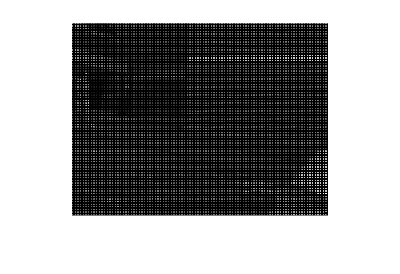

% img = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\WalkSequence\Colour\walking_14.png');
% img = im2gray(img); %240 320
% % Initialize the output image
% output = zeros(size(img));
% % Subsample the image
% for i = 1:2:size(img, 1)
%     for j = 1:2:size(img, 2)
%         output(i, j) = img(i, j);
%     end
% end
% imshow(output, []);

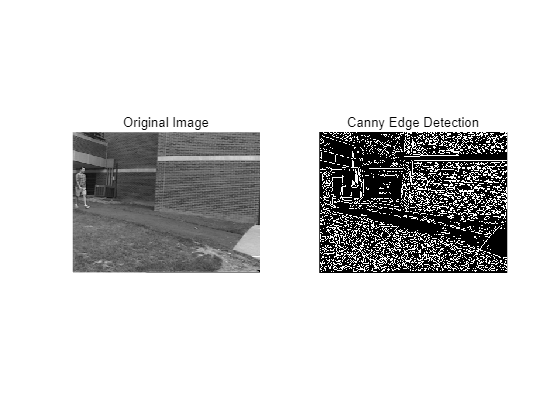

I = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\WalkSequence\Colour\walking_14.png');
if size(I,3) == 3
    I = rgb2gray(I);
end

THRESH = [0.05, 0.08]; 
SIGMA = 0.5;
% 使用Canny边缘检测
BW = edge(I,'canny',THRESH,SIGMA);

figure;
subplot(1,2,1); imshow(I); title('Original Image');
subplot(1,2,2); imshow(BW); title('Canny Edge Detection');

function sobel_result = sobel_edge_enhancement(img)
    Gx = [-1 0 1; -2 0 2; -1 0 1];
    Gy = [-1 -2 -1; 0 0 0; 1 2 1];

    dx = conv2(double(img), Gx, 'same');
    dy = conv2(double(img), Gy, 'same');

    sobel_result = sqrt(dx.^2 + dy.^2);
end

% 高斯滤波器函数
function result = gaussian_filter(img, size)
    sigma = size/6;
    ind = -floor(size/2) : floor(size/2);
    [X, Y] = meshgrid(ind, ind);
    h = exp(-(X.^2 + Y.^2) / (2*sigma^2));
    h = h / sum(h(:));
    % 使用conv2函数对图像进行滤波
    result = conv2(double(img), h, 'same');
end



% 基于[1,-1]梯度算子的边缘增强方法
function custom_result = custom_edge_enhancement(img)
    H = [1, -1];
    V = H';
    dx = conv2(double(img), H, 'same');
    dy = conv2(double(img), V, 'same');
    custom_result = sqrt(dx.^2 + dy.^2);
end
